Initialization

clear;
close all;
delete(findall(0,'Type','figure'))

Download data from CMS open data website.

We are interested in$J/\psi$ $\to$$\mu \mu
$ events.

location='http://opendata.cern.ch/record/545';
web(location)
fln='Jpsimumu.csv';
url=[location,'/files/',fln];

if ~exist(fln) 
    disp(['Downloading ',fln,' from ',url,'.'])
    websave(fln,url);
else
    disp(['File ',fln,' exists so will not be downloaded.'])
end

File Jpsimumu.csv exists so will not be downloaded.


Read .csv file, import the data as a table and check the variables of each column:

tbl=readtable(fln);
columnNames = tbl.Properties.VariableNames;
disp(columnNames);

    {'Run'}    {'Event'}    {'type1'}    {'E1'}    {'px1'}    {'py1'}    {'pz1'}    {'pt1'}    {'eta1'}    {'phi1'}    {'Q1'}    {'type2'}    {'E2'}    {'px2'}    {'py2'}    {'pz2'}    {'pt2'}    {'eta2'}    {'phi2'}    {'Q2'}



Turn data of interest in to vectors:

Run = tbl.Run;
Event = tbl.Event;
E1 = tbl.E1;
px1 = tbl.px1;
py1 = tbl.py1;
pz1 = tbl.pz1;
pt1 = tbl.pt1;
eta1 = tbl.eta1;
phi1 = tbl.phi1;
Q1 = tbl.Q1;
E2 = tbl.E2;
px2 = tbl.px2;
py2 = tbl.py2;
pz2 = tbl.pz2;
pt2 = tbl.pt2;
eta2 = tbl.eta2;
phi2 = tbl.phi2;
Q2 = tbl.Q2;

First look at the data. Plot the histogram of energy (E1) distribution. 

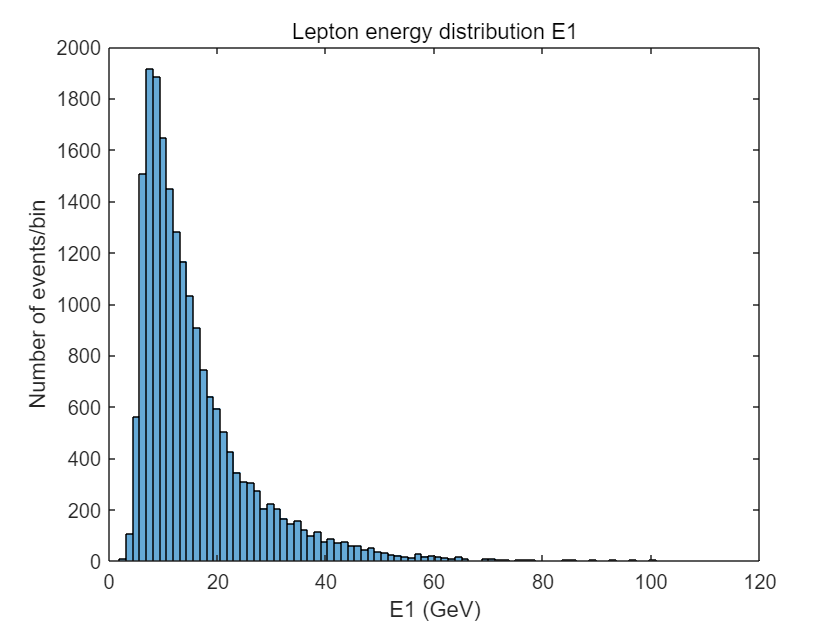

nbins=200;
figure;
histogram(E1,nbins);
xlim([0 120])
title('Lepton energy distribution E1') 
xlabel('E1 (GeV)')
ylabel('Number of events/bin')

Then is  pseudo-rapidity eta1：

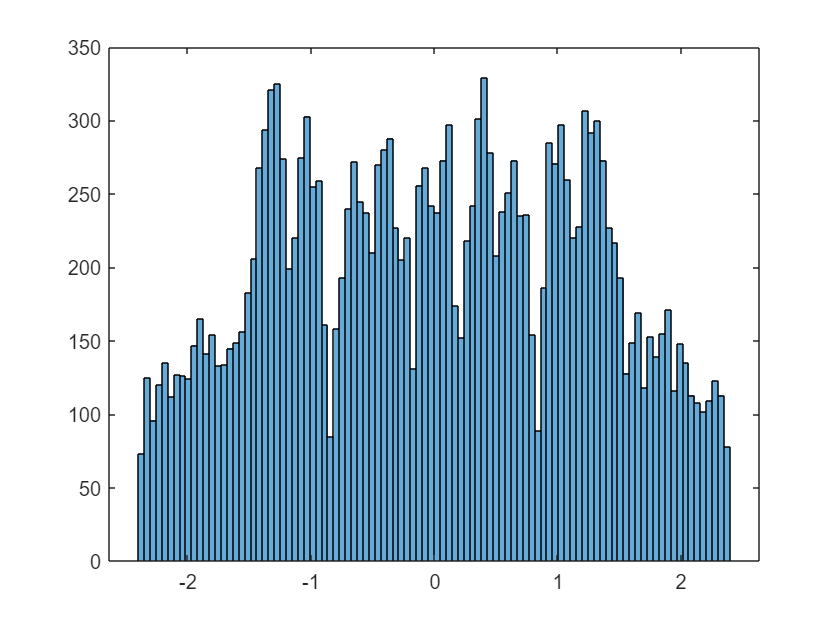

nbins=100;
figure;
histogram(eta1,nbins);

Use the formula $m^2 =E^2 -{\vec{p} }^2$ to calculate the mass distributions of the two muons of final state.

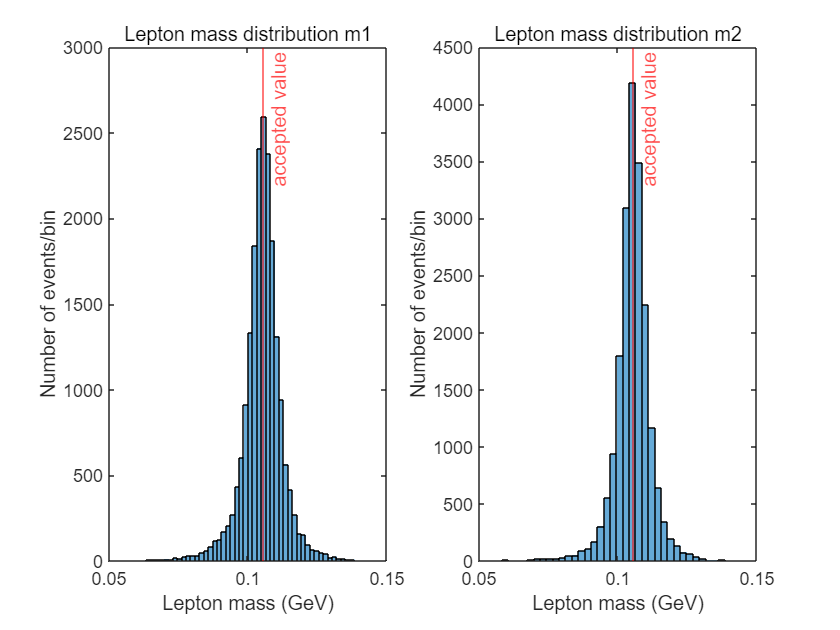

m1= (abs(E1.^2-px1.^2-py1.^2-pz1.^2)).^(1/2);
m2= (abs(E2.^2-px2.^2-py2.^2-pz2.^2)).^(1/2);
nbins=200; 
 
subplot(1,2,1)
histogram(m1,nbins);
xline(0.1056583755,'-r','accepted value')
title('Lepton mass distribution m1') 
xlabel('Lepton mass (GeV)')
ylabel('Number of events/bin')
xlim([0.05,0.15])

subplot(1,2,2)
histogram(m2,nbins);
xline(0.1056583755,'-r','accepted value')
title('Lepton mass distribution m2') 
xlabel('Lepton mass (GeV)')
ylabel('Number of events/bin')
xlim([0.05,0.15])

Check there exists no event such that two muons of final state having the same charge. 

samesign=length(Q2(Q1~=-Q2))

samesign = 0

`Reconstructing the mass spectrum of initial-state particles from two-muon events in the final state (system invariant mass)`

mll=(abs((E1+E2).^2-(px1+px2).^2-(py1+py2).^2-(pz1+pz2).^2)).^(1/2);
figure;
h=histogram(mll(Q1~=Q2),nbins);
    hold on
%set(gca,'YScale','log')
title('Lepton pair mass distribution')

xlabel('Lepton pair mass (GeV)')
ylabel('Number of events/bin')

`We can observe a sharp peak at approximately 3.1 GeV, corresponding precisely to the `$J/\psi$` particle mass.`

`However, there is another less prominent peak at around 3.7 GeV.`

`For a more rigorous analysis, we employ the findpeaks function to identify local maxima for peak analysis:` 

`First, convert the histogram into a series of discrete points where x corresponds to each bin position and y corresponds to each bin height.`

x=h.BinEdges(1:end-1)+h.BinWidth/2.;
y=h.Values;

`minprom specifies the minimum prominence required for peak identification as a criterion;`

`Set NpeakMax to limit the maximum number of peaks to 100 (to prevent excessive detection);`

`Additionally, require peaks to have a minimum width of at least two bins to prevent single-bin anomalies from affecting peak detection.`

minprom=60;
NpeakMax=100;
minpeakwidth=2*h.BinWidth

minpeakwidth = 0.0302

[pks,locs, widths, proms]=findpeaks(y,x,'SortStr','descend',...
 'NPeaks',NpeakMax,'MinPeakProminence',minprom,'MinPeakWidth',minpeakwidth)

pks =         1862          97


locs =     3.0862    3.7061


widths =     0.0675    0.0825


proms =         1825          74


`With 'SortStr' set to 'descend', peaks are sorted in descending order. We obtain four key properties for the two peaks in the energy spectrum:` 

`Peak values (pks), positions (locs), full width at half maximum (widths), and relative prominence (proms).`

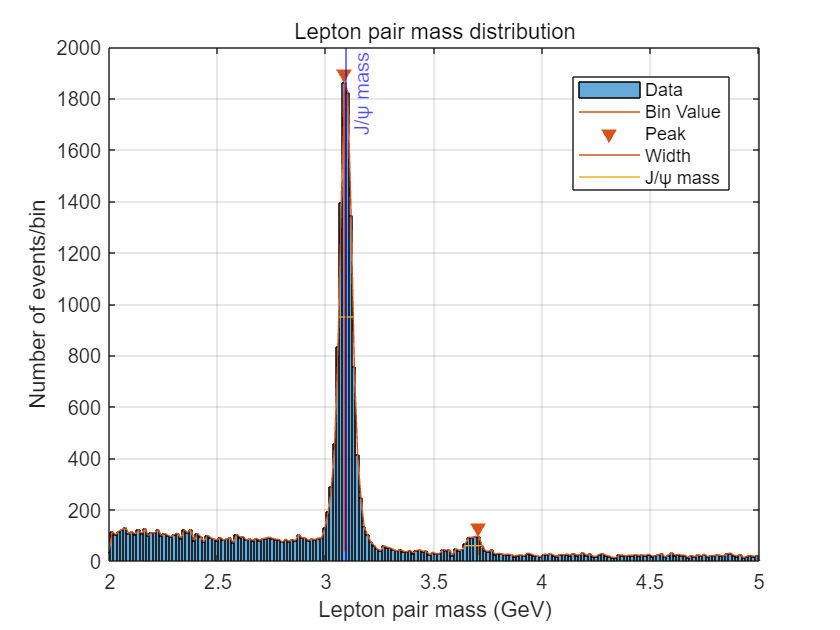

findpeaks(y,x,'SortStr','descend','Annotate','extents',...
 'NPeaks',NpeakMax,'MinPeakProminence',minprom,'MinPeakWidth',minpeakwidth)
xline(3.096916,'-b','J/ψ mass')
legend('Data','Bin Value','Peak','Width');
ylim([0,2000])

`Now comes the crucial part: calculating significance.`

Npeaks=length(pks);
N=length(mll);
Ntot=zeros(Npeaks,1);

`Store the number of background events above and below each peak, along with the average background events per peak:`

Nbackground_below=Ntot;
Nbackground_above=Ntot;
Nbackground=Ntot;

`Store the signal fraction and significance for each peak:`

Fraction=Ntot;
PeakSig=Ntot;

for ipeak=1:Npeaks
    Ntot(ipeak)=length(mll(mll>locs(ipeak)-widths(ipeak)&...
        mll<locs(ipeak)+widths(ipeak))); 
    Nbackground_below(ipeak)=length(mll(mll>locs(ipeak)-2*widths(ipeak)&...
        mll<locs(ipeak)-widths(ipeak))); 
    Nbackground_above(ipeak)=length(mll(mll>locs(ipeak)+widths(ipeak)&...
        mll<locs(ipeak)+2*widths(ipeak))); 
    Nbackground(ipeak)=(Nbackground_below(ipeak)+Nbackground_above(ipeak))/2;
    Nsignal(ipeak)=Ntot(ipeak)-Nbackground(ipeak); 
    Fraction(ipeak)=Nsignal(ipeak)/N;
    PeakSig(ipeak)= Nsignal(ipeak)/max(sqrt(Nbackground(ipeak)),1);
end

PeakSig

PeakSig =   360.6501
   38.2485


`Next, perform Gaussian fitting for the two peaks within regions spanning one peak width on either side of the peak positions.`

`Parameter estimation yields the sample mean and standard deviation of the fitted curves.`

`This approach helps us determine more rigorous particle masses and provide confidence intervals.`

`The relationship between normal distribution confidence intervals and standard deviation is illustrated below:`

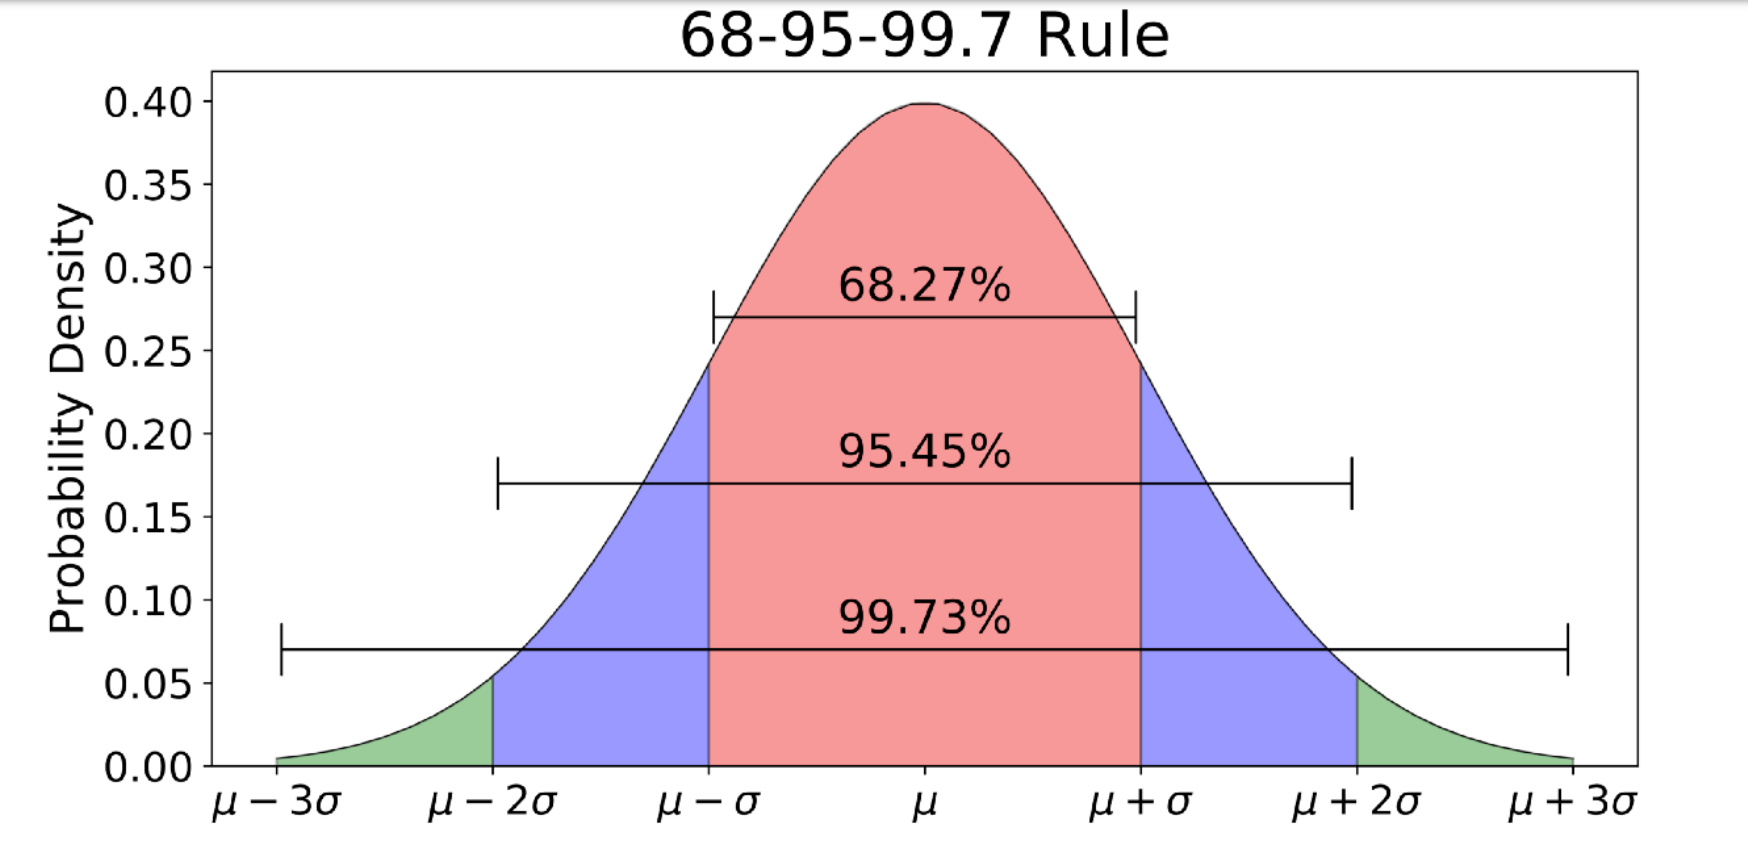

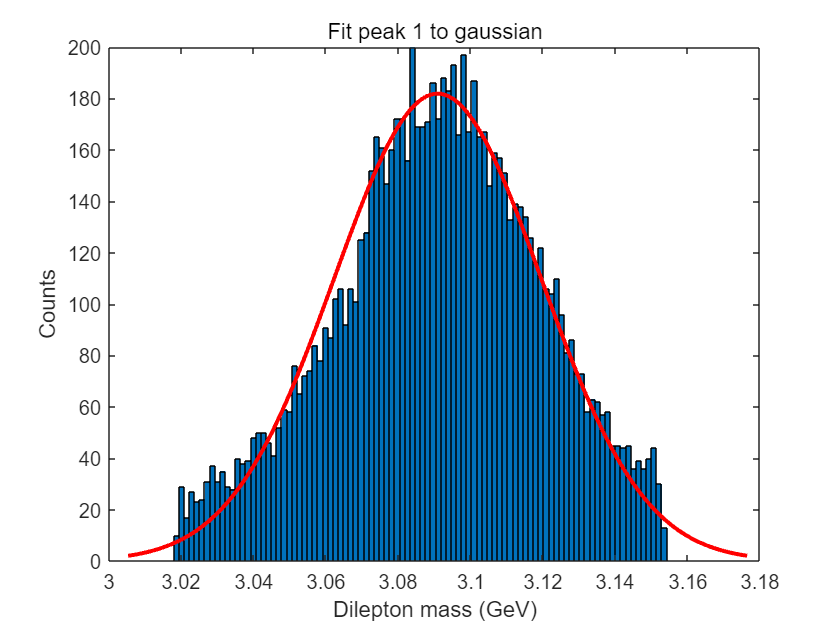

pd1 =   NormalDistribution

  正态 分布
       mu =   3.09087   [3.09029, 3.09146]
    sigma = 0.0285251   [0.0281179, 0.0289443]


mfit = 3.0909

mfitCLvalues =     3.0903    3.0915


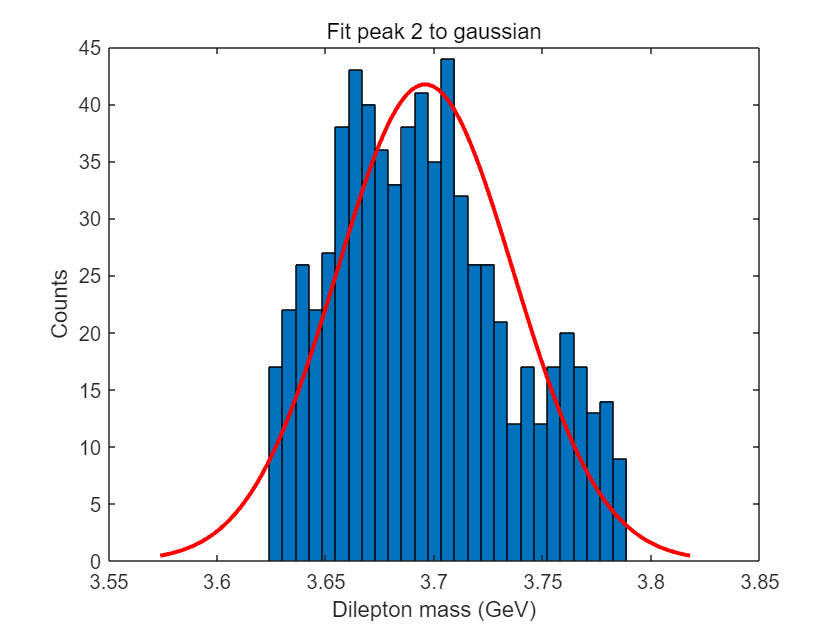

pd1 =   NormalDistribution

  正态 分布
       mu =   3.69568   [3.69266, 3.69871]
    sigma = 0.0407036   [0.0386746, 0.042959]


mfit = 3.6957

mfitCLvalues =     3.6935    3.6978


for ipeak=1:Npeaks
    range1=mll>locs(ipeak)-widths(ipeak)&mll<locs(ipeak)+widths(ipeak);
    figure
    histfit(mll(range1))
    title(['Fit peak ',num2str(ipeak),' to gaussian'])
    xlabel('Dilepton mass (GeV)');ylabel('Counts')

    pd1 = fitdist(mll(range1),'Normal')
    mfit=pd1.mu
    stdParmeters=sqrt(diag(pd1.ParameterCovariance));
    std1=stdParmeters(ipeak);

    mfitCLvalues=[mfit-1.96*std1,mfit+1.96*std1]
end

`The obtained mass estimate of 3.0909 GeV is relatively close to the currently accepted value of the `$J/\psi$` particle (3.096916 GeV).`

`Although the error is approximately 0.2%, this analysis remains less precise compared to genuine experimental analyses.`

`More rigorous results should incorporate systematic uncertainties from all possible sources and employ improved statistical methods.`

`Here we present an alternative, albeit slightly rougher, method for obtaining the mass and its 95% confidence interval.`

for ipeak=1:Npeaks
    range1=mll>locs(ipeak)-widths(ipeak)&mll<locs(ipeak)+widths(ipeak);

    mean(mll(range1)) 
    std(mll(range1)) 
    Nevents=length(mll(range1))
    std1_direct= std(mll(range1))/sqrt(Nevents) 
    [muHat,sigmaHat,muCI,sigmaCI] = normfit(mll(range1),0.05)
    (muCI(2)-muCI(1))/2.
end

ans = 3.0909

ans = 0.0285

Nevents = 9159

std1_direct = 2.9806e-04

muHat = 3.0909

sigmaHat = 0.0285

muCI =     3.0903
    3.0915


sigmaCI =     0.0281
    0.0289


ans = 5.8426e-04

ans = 3.6957

ans = 0.0407

Nevents = 698

std1_direct = 0.0015

muHat = 3.6957

sigmaHat = 0.0407

muCI =     3.6927
    3.6987


sigmaCI =     0.0387
    0.0430


ans = 0.0030